# Modeling stuff for fun

I've written some simple code to model and simulate spreads of various things. The codes gets more and more complicated as I proceed.

#### Simple model

Simple model where the healthy individuals and infected move randomly in a rectangle.

Initializations:

frames =    100;
m =          100; %number of samples
ini_inf = 1;
X = zeros(m, 3);                %positions
num_inf = zeros(m, 2);
num_inf(1, 1) = 1;
num_inf(1, 2) = ini_inf;
radius = 6;                     %radius of spread
velocity = 5;                   %velocity of movement
x_min = 0;
x_max = 200;
y_min = 0;
y_max = 200;
X(:,1) = (x_max - x_min)*rand(m,1);       %initialization
X(:,2) = (y_max - y_min)*rand(m,1);
X_uinf = zeros(size(X));
X_inf = zeros(size(X));
X = initialize_inf(X, ini_inf);

In this version of MATLAB, to enable for loop animations, we need to set the following as *True*:

s = settings;
s.matlab.editor.AllowFigureAnimation.PersonalValue = true;

The loop prints both healthy and infected populations, then proceeds to update the locations with random movements and checks for new infections based on promixity.

tiledlayout(2,2)
for i=1:frames
   clf
    X_uinf = X((X(:,3) == 0),:);
    X_inf = X((X(:,3) == 1),:);
    num_inf(i, :) = [i size(X_inf, 1)];
    
    nexttile
    plot(X_uinf(:,1), X_uinf(:,2), '*b');
    hold on;
    plot(X_inf(:,1), X_inf(:,2), 'vr');
    title(sprintf('Spread simulation (frame = %.1f)',i));
    xlim([x_min, x_max]);
    ylim([y_min, y_max]);
    
    nexttile([1 2])
    plot(num_inf(1:i, 1), num_inf(1:i, 2));
    xlim([1, frames]);
    ylim([0, m]);
    title('Infection growth');
    
    drawnow
    
    X(:,1:2) = update_position(X(:,1:2), velocity, x_min, x_max, y_min, y_max);
    X(:,3) = update_status(X, radius);
    pause(0.01);
end
hold off

#### Simulating Zombies

Let's attempt at simulating a zombie outbreak!

We make the following assumptions about humans:

- Moves away in a direction away from all zombies within a scope. Moves away from the weighted centroid, weights determined by a gaussian on distance of separation.

- Can move at normal speed and sprint at 1.25 x speed.

- Gets tired in periodic intervals. Speed reduces to 0.75 on sprinting for 10 frames and takes 10 frames to recover.

We make the following assumptions about zombies:

- Speed: 1.25 x humans (not sure of exact xD, just that they are faster)

- Directional motion, towards closest human.

- Cannot detect human prescence beyond a distance.

- On contact, conversion takes some time, can be varied in simulation.

clear
%Bounds
x_min = 0;
x_max = 100;
y_min = 0;
y_max = 100;
frames = 200;

%zombie and human initialization
total_init_num = 100;           %initial number of humans + zombies
z_init_num = 2;                 %initial number of zombies
h_speed = 4;                    %human speed
speed_ratio = 1.25;             %h:z speed ratio
z_speed = h_speed*speed_ratio;  %zombie speed
speed_tired_ratio = 0.75;       %speed at tired state ratio
speed_tired = h_speed*speed_tired_ratio;
tired_frames_count = 10;        % no. of frames spent at lower speed for every equal number of frames
zombie_radius = 40;             %field of vision for zombie
human_radius = 40;              %field of vision for humans
infection_radius = 10;
conversion_time = 3;            % conversion rate (no. frame(s))
num_inf = zeros(total_init_num, 2);
num_inf(1, 1) = 1;
num_inf(1, 2) = z_init_num;

z = struct('speed', z_speed, 'radius', zombie_radius, 'infect_radius', infection_radius, 'conv_time', conversion_time);
h = struct('speed_sprint', h_speed, 'speed', speed_tired, 'tired_frames', tired_frames_count, 'radius', human_radius);
bound = struct('x_min', x_min, 'x_max', x_max, 'y_min', y_min, 'y_max', y_max);

%position initializations
X = zeros(total_init_num, 7);
X(:,1) = (x_max-x_min).*rand(total_init_num,1);
X(:,2) = (y_max-y_min).*rand(total_init_num,1);
X(1:z_init_num,3) = 1;
X(:,4) = 0;
X(:,5) = tired_frames_count;
X_uinf = zeros(size(X));
X_inf = zeros(size(X));
X_conv = zeros(size(X));

s = settings;
s.matlab.editor.AllowFigureAnimation.PersonalValue = true;

Update loop

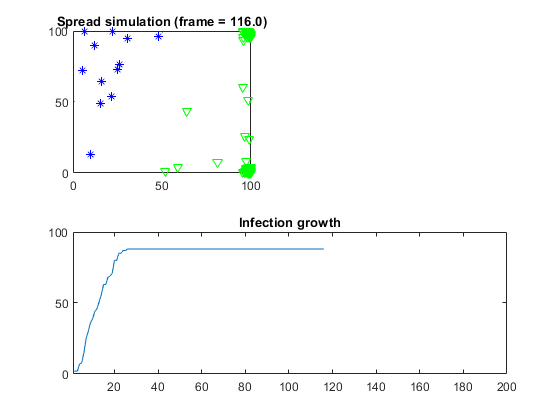

tiledlayout(2,2)

for i=1:frames
   clf
    X_uinf = X((X(:,3) == 0),:);
    X_inf = X((X(:,3) == 1),:);
    X_conv = X(((X(:,3) ~= 1)&(X(:,3) ~= 0)),:);
    num_inf(i, :) = [i size(X_inf, 1)];
    
    nexttile
    plot(X_uinf(:,1), X_uinf(:,2), '*b');
    hold on;
    plot(X_inf(:,1), X_inf(:,2), 'vg');
    plot(X_conv(:,1), X_conv(:,2), 'oy');
    title(sprintf('Spread simulation (frame = %.1f)',i));
    xlim([x_min, x_max]);
    ylim([y_min, y_max]);
    
    nexttile([1 2])
    plot(num_inf(1:i, 1), num_inf(1:i, 2));
    xlim([1, frames]);
    ylim([0, total_init_num]);
    title('Infection growth');
    
    drawnow
    
    X = update_status_zombie(X, z, h);
    X = update_position_zombie(X, z, h, bound);
    pause(0.01);
end
hold off